# The displacement vector field $u$

This is a place where we can play with the vector field $u$ and add some other form of noise to the data.

## 1    The crystal lattice

For reference, shown here is an undistorted crystal lattice (basically a product of sinusoids) produced by substituting $\vec{u}=\vec{0}$ to equation S5 of Lawler-Fujita (2010)'s supplementary material.

Creating the lattice and applying the Fourier transform to the created image.

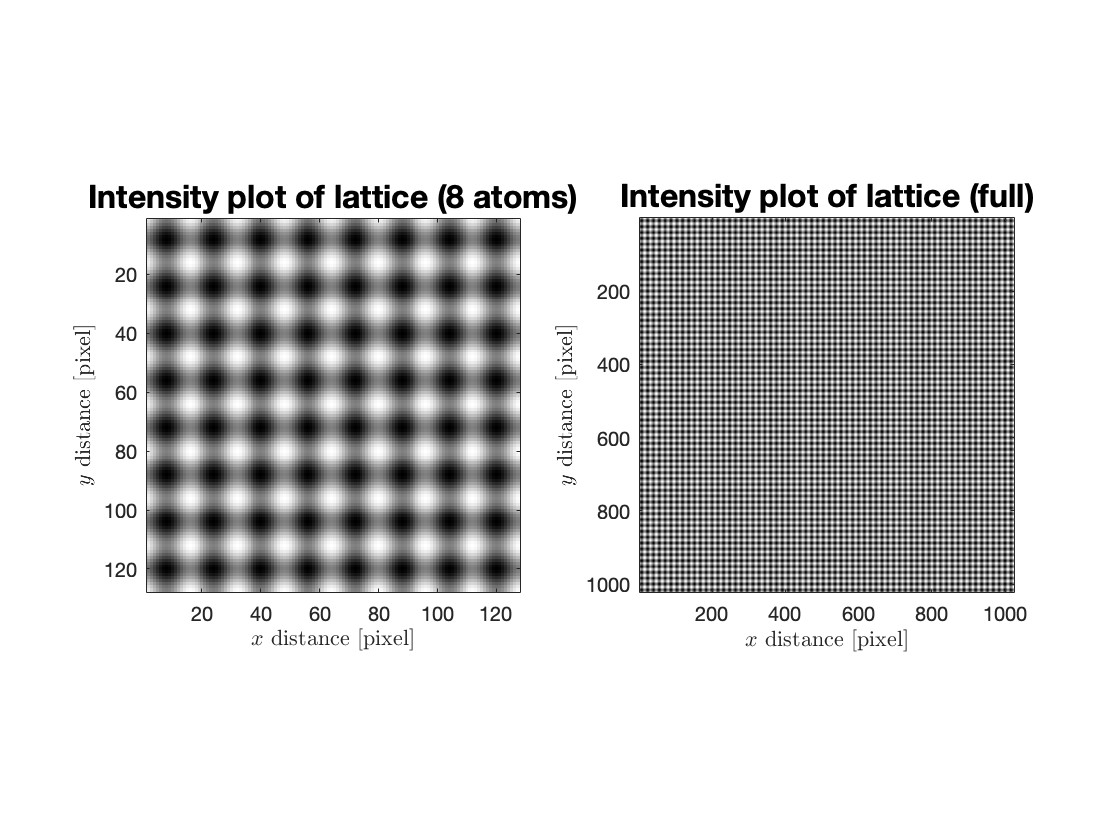

image_length = 1024;
image_height = 1024;
atom_diameter = 16;

Q_x = [1 0];
Q_y = [-Q_x(2) Q_x(1)]; % just to ensure orthogonality
Q_x = Q_x * 2*pi / (norm(Q_x)*atom_diameter);
Q_y = Q_y * 2*pi / (norm(Q_y)*atom_diameter);

lattice = normies(uTransform(uCreate(image_height,image_length,0) ...
    ,Q_x,Q_y)); % notice the zero
comboPlot(lattice,"lattice",atom_diameter);

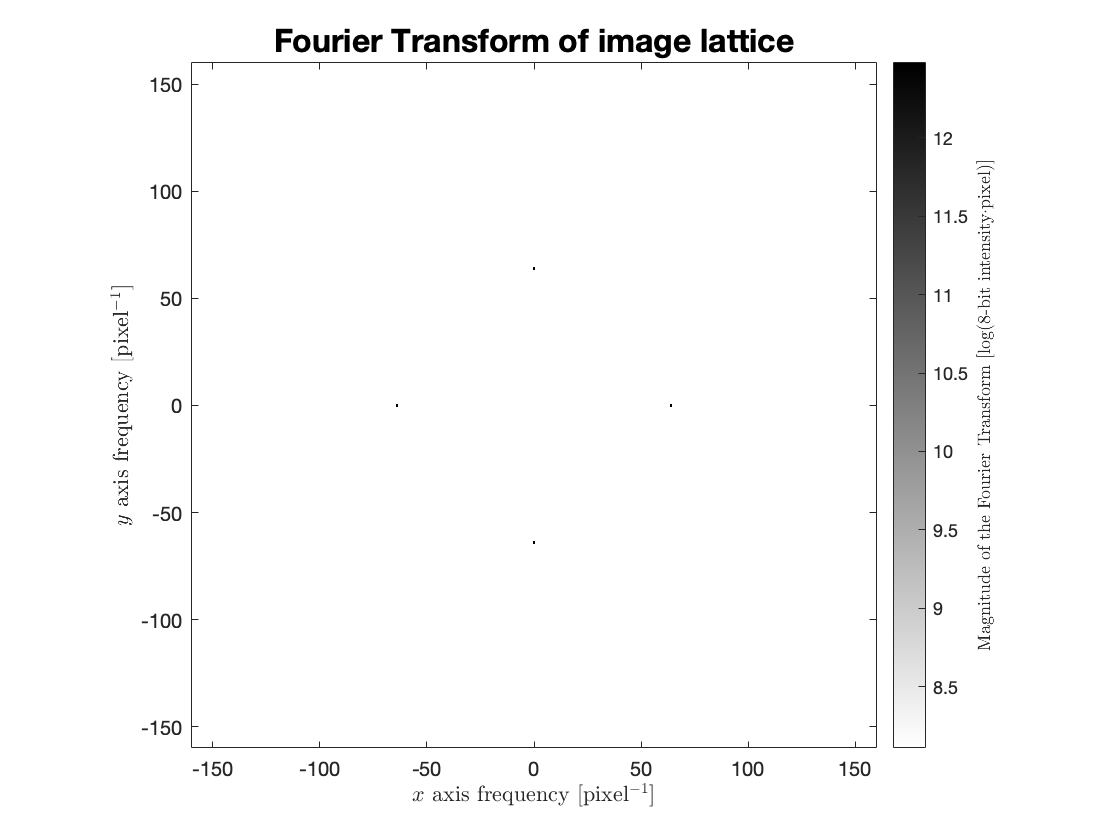

lattice_fft = myFFT(lattice,"lattice");

## 2    A distorted crystal lattice

We create a distorted lattice with the displacement vector [UNSPECIFIED] and apply the Fourier transform to the distorted image.

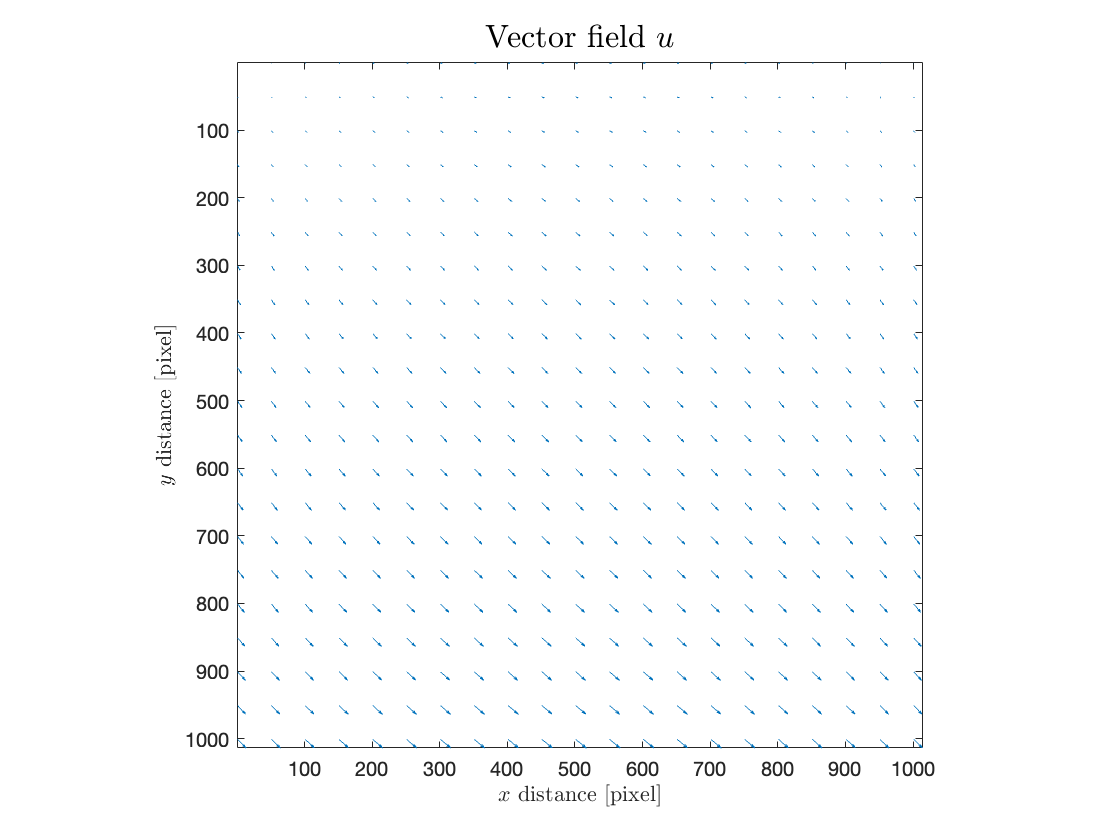

u = uCreate(image_height,image_length,atom_diameter,[1 1],[1 1],[0 0]);
% the third parameter specifies the maximum displacement vector magnitude
% the first vector is the x,y for drift
% the second vector is the x,y for hysteresis
% the third vector is the x,y for creep

uPlot(u,"$u$");

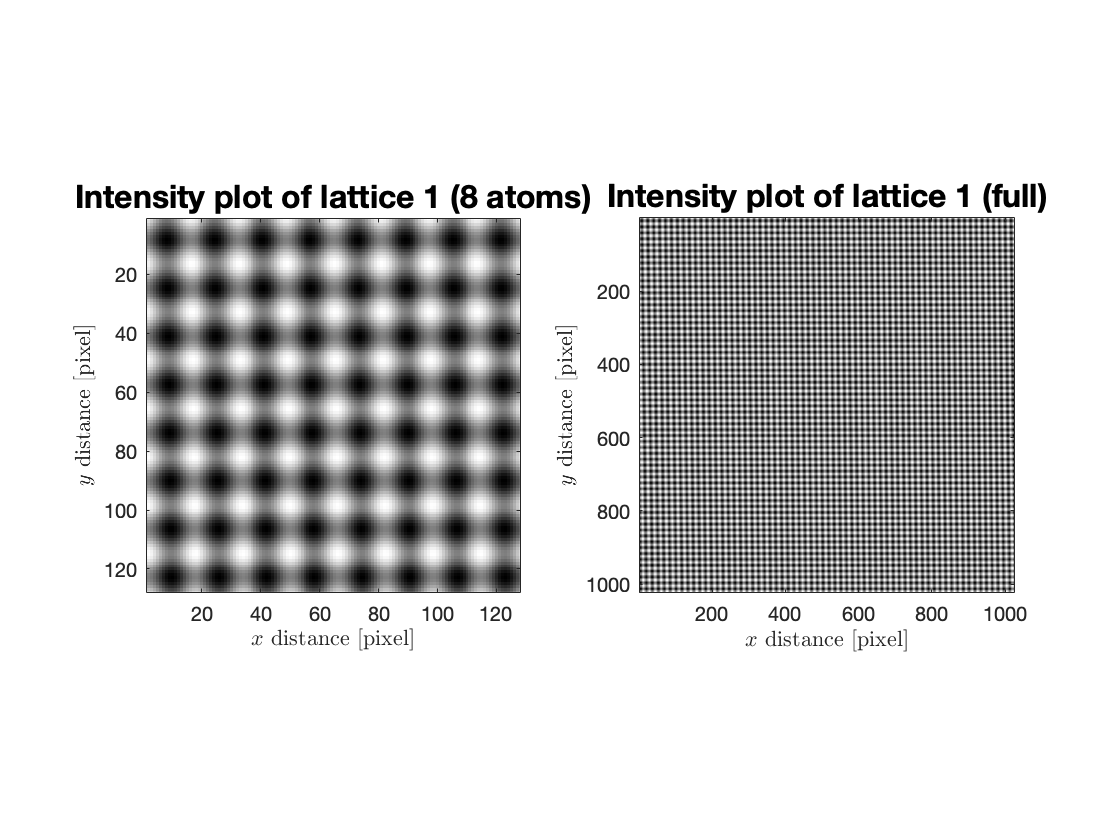


lattice1 = normies(uTransform(u,Q_x,Q_y));
comboPlot(lattice1,"lattice 1",atom_diameter);

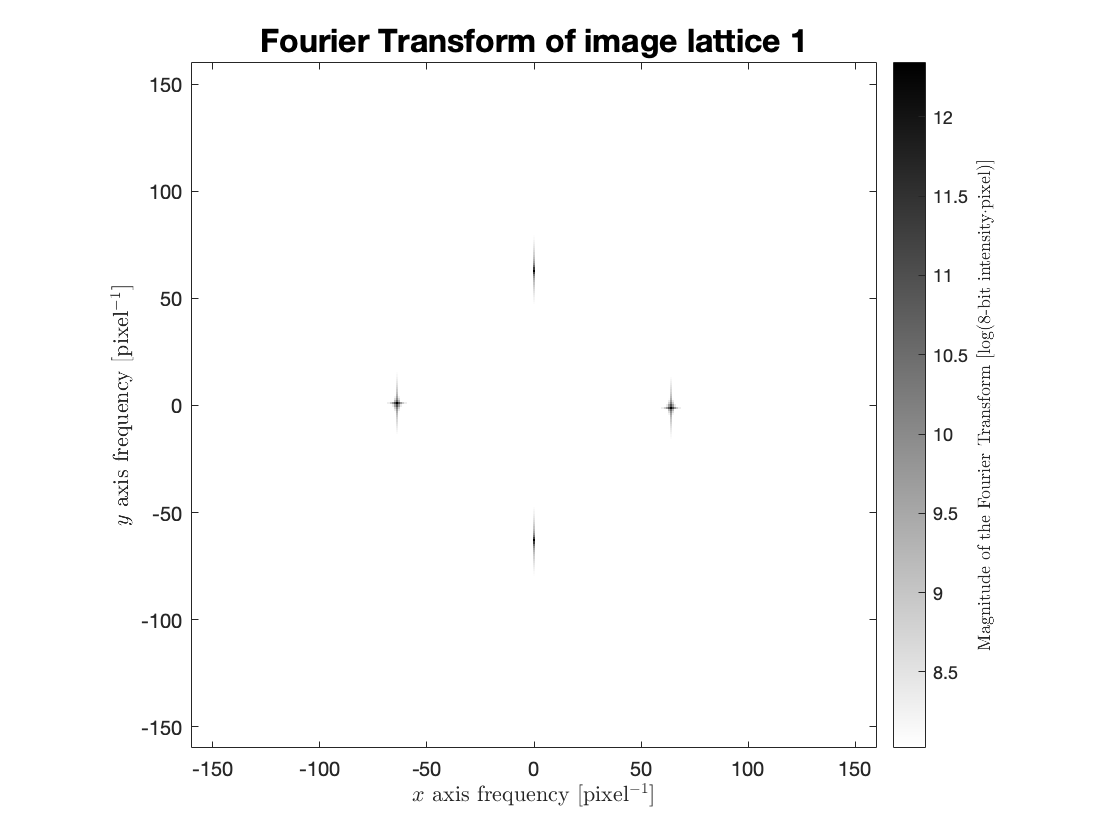


lattice1_fft = myFFT(lattice1,"lattice 1");

## 3    Calculating the vector field $u$

We're going to pretend that we don't know the displacement vector field that resulted to lattice1. Let's calculate $u$ only from the matrix/image lattice1.

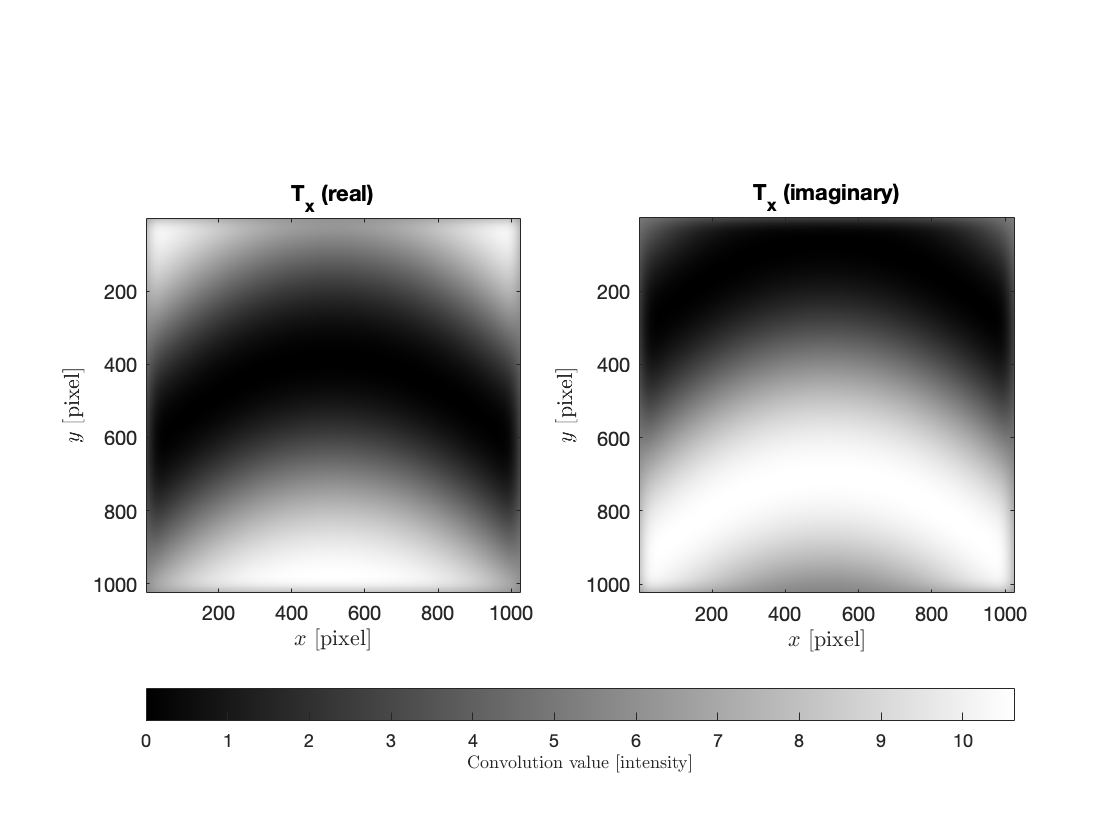

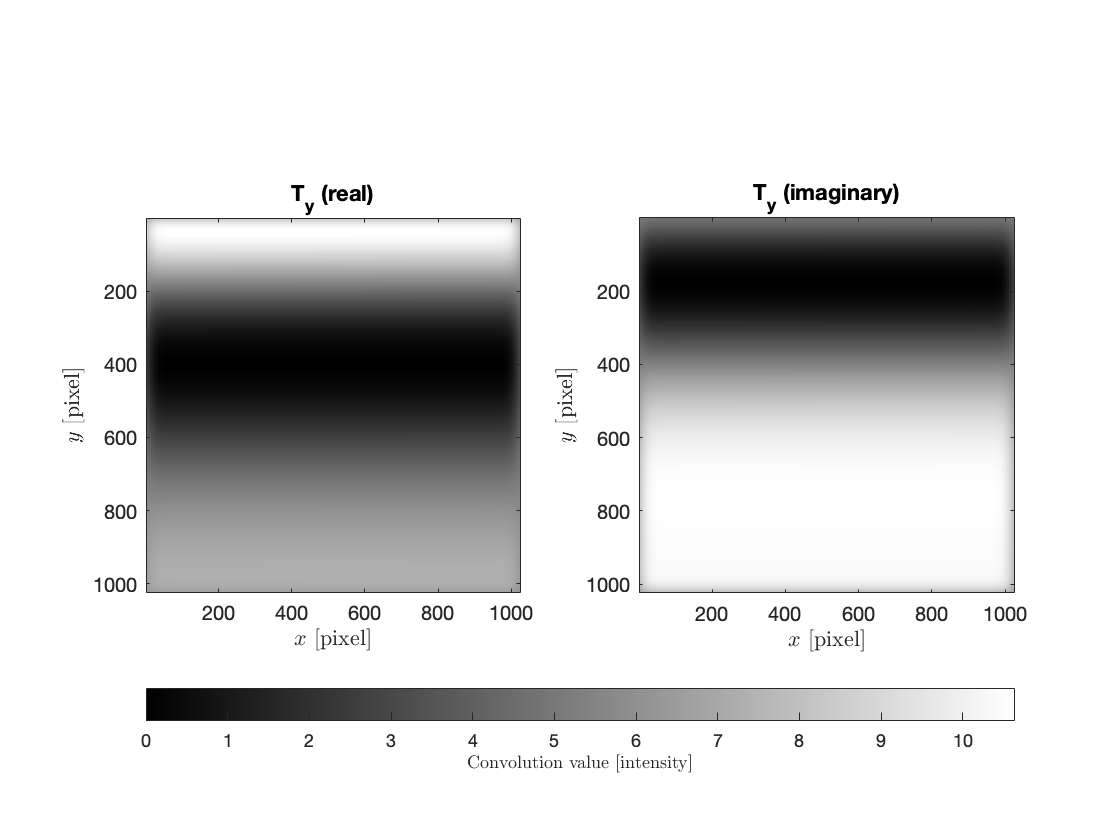

lambda = 0.05;

tic
ucalc = myConv(lattice1,Q_x,Q_y,lambda);

toc

Elapsed time is 18.489057 seconds.


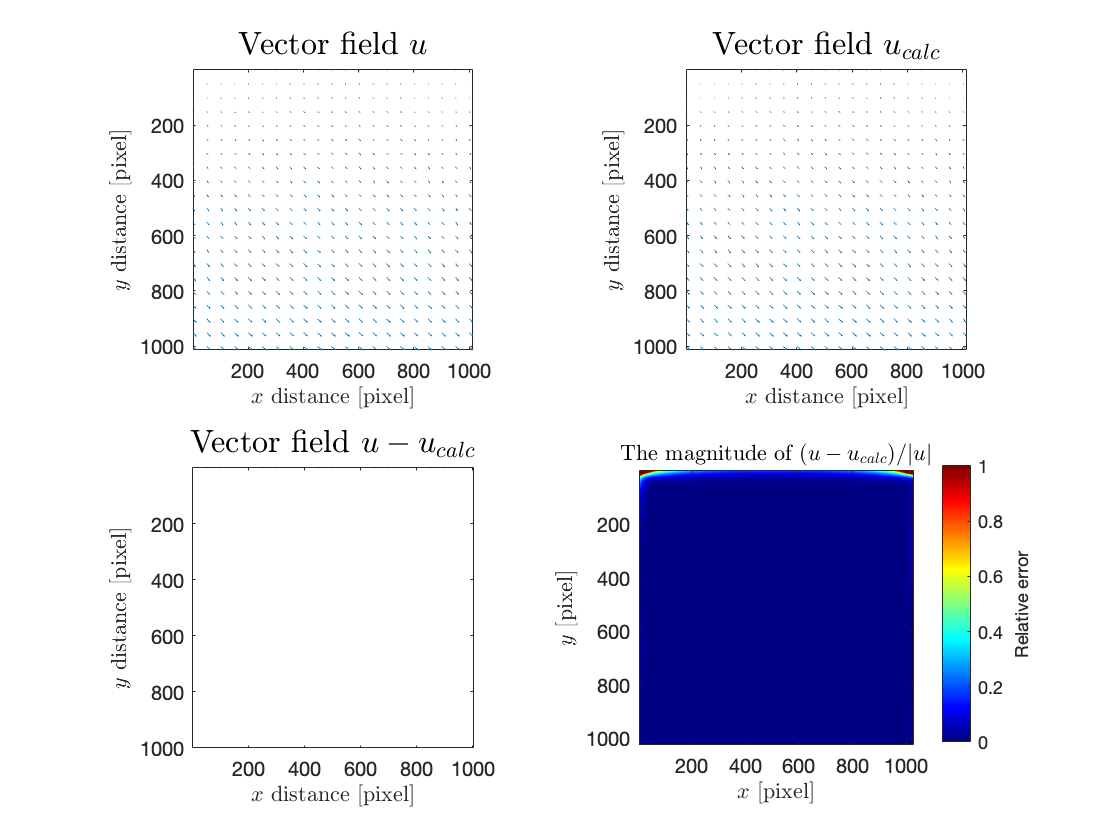


uComboPlot(u,ucalc);

Notice the wanky edges on the $T_x$ and $T_y$ plots. That's because the convolution function in MatLab padds the matrices with zeros on the edges.

## 4    Adding a random contour as topographic noise

This generates a random but approximately smooth topographic noise by assigning random numbers and then solving the Laplace equation with free boundaries by relaxation.

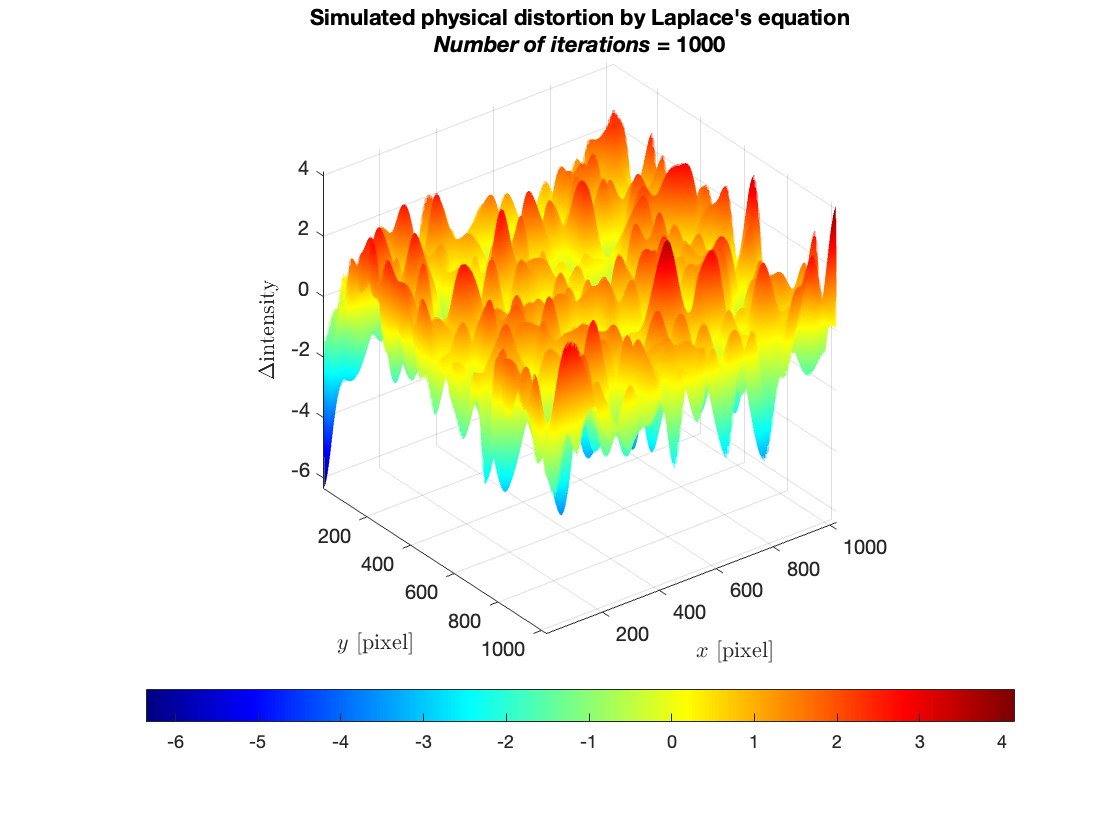

tic
noise = noiseLaplace(image_height,image_length,atom_diameter);

toc

Elapsed time is 5.392179 seconds.


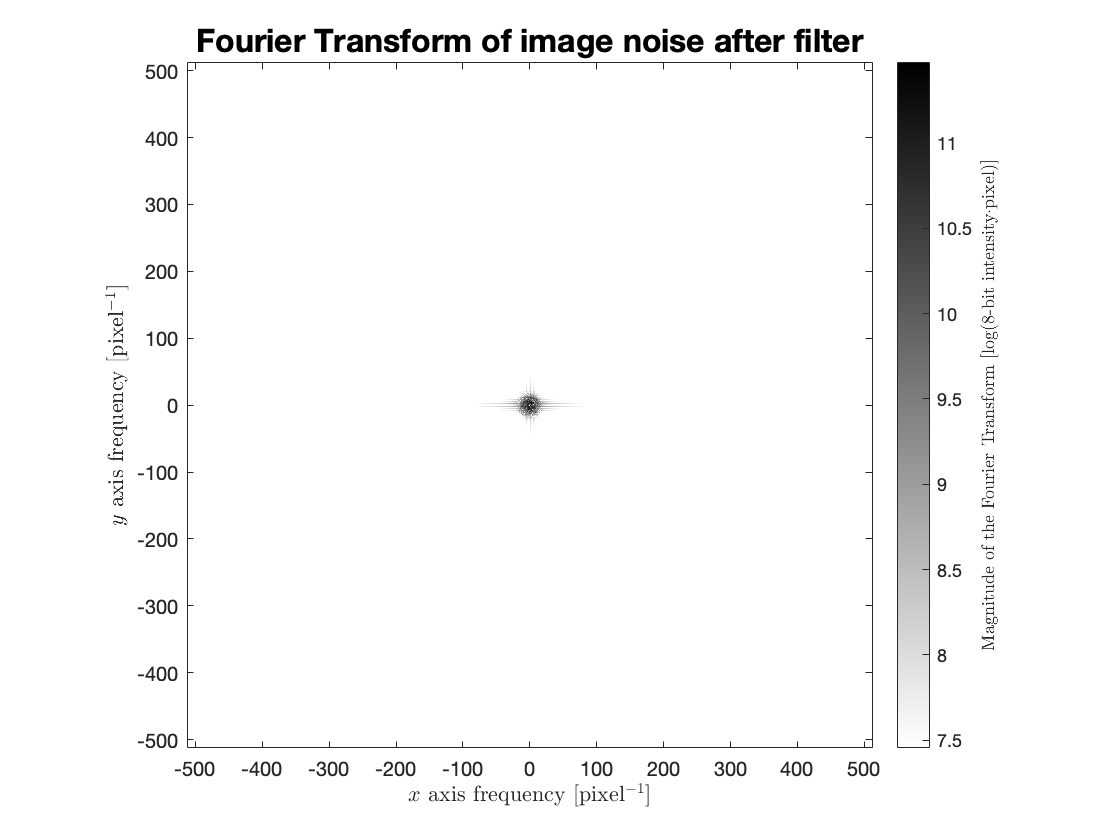


% noise = randn(image_height,image_length);

noise = real(ifft2(myFFT(noise,"noise",[],atom_diameter)));

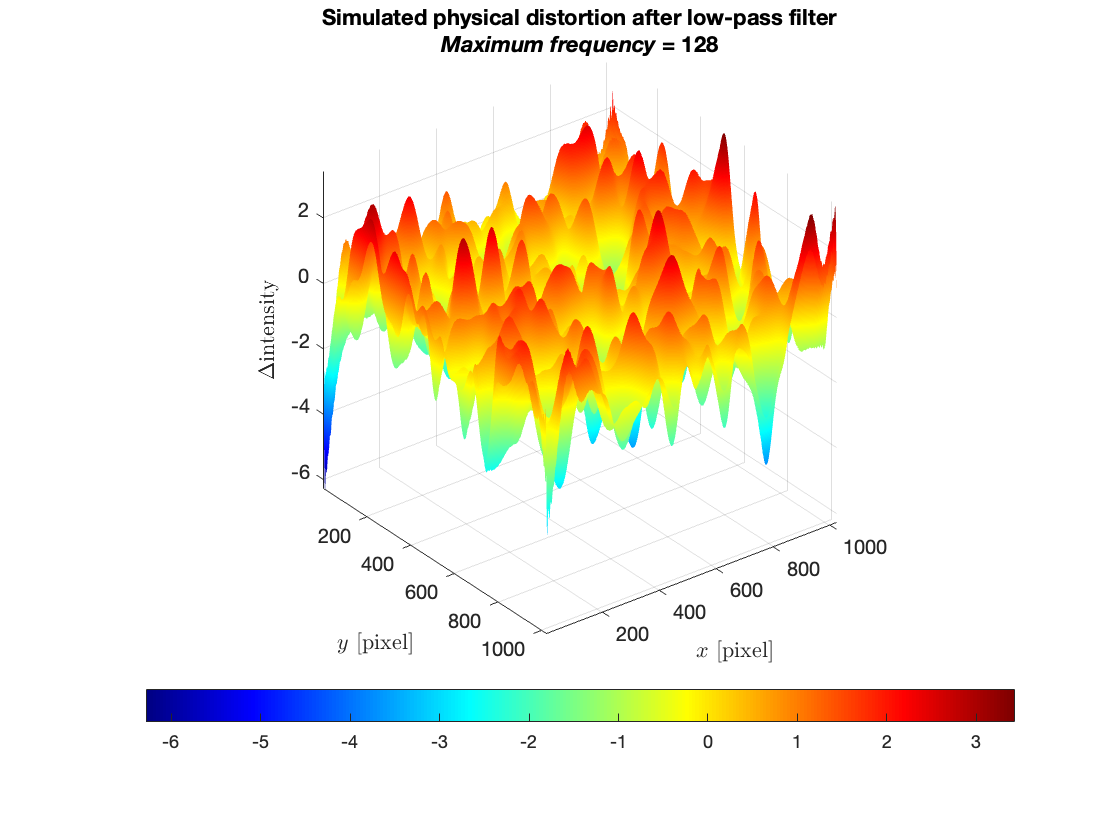

noise = 1*(noise-mean(noise,"all"))/std(noise,1,"all");

laplacePlot(image_height,image_length,noise,[],atom_diameter);

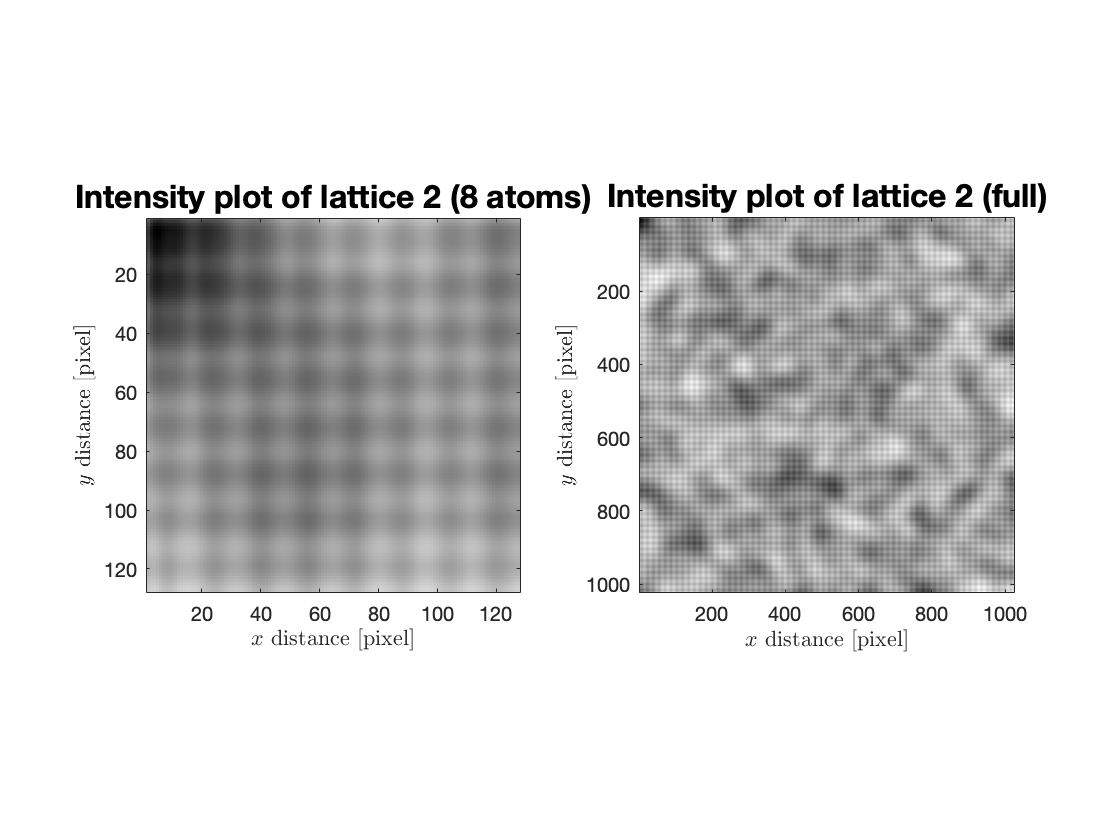

lattice2 = lattice+noise;
comboPlot(lattice2,"lattice 2",atom_diameter);

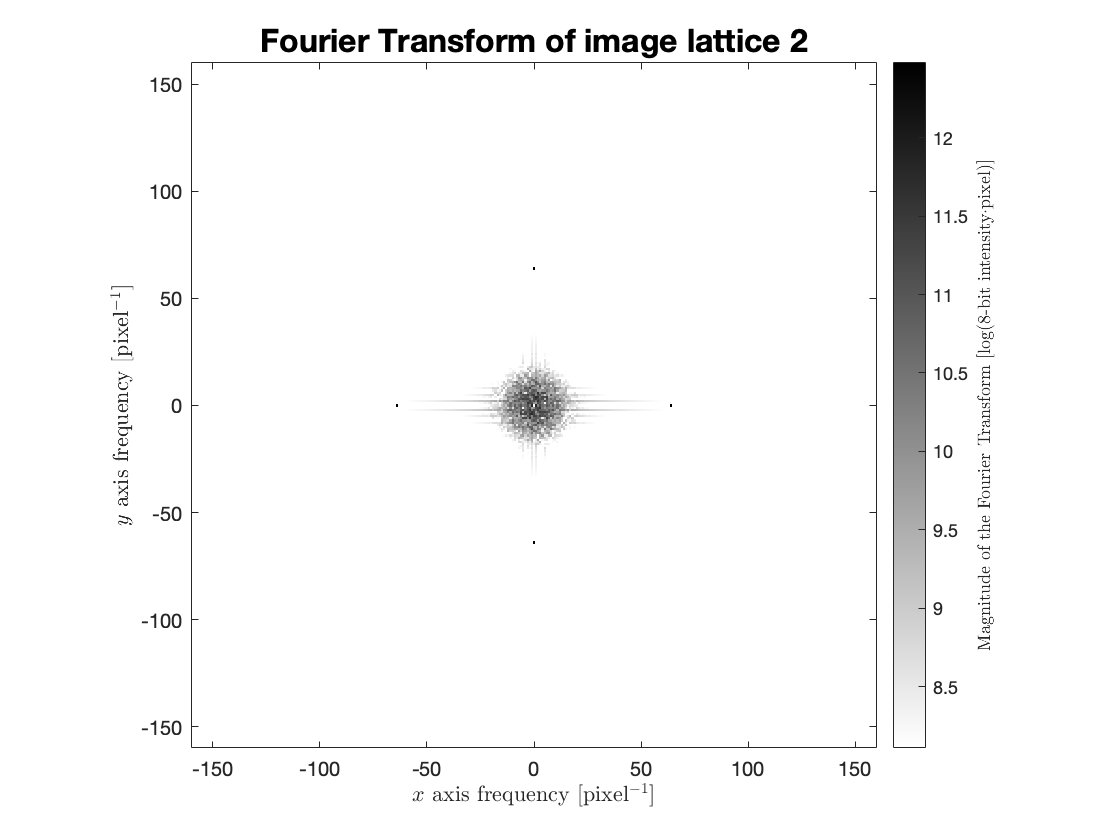

lattice2_fft = myFFT(lattice2,"lattice 2");

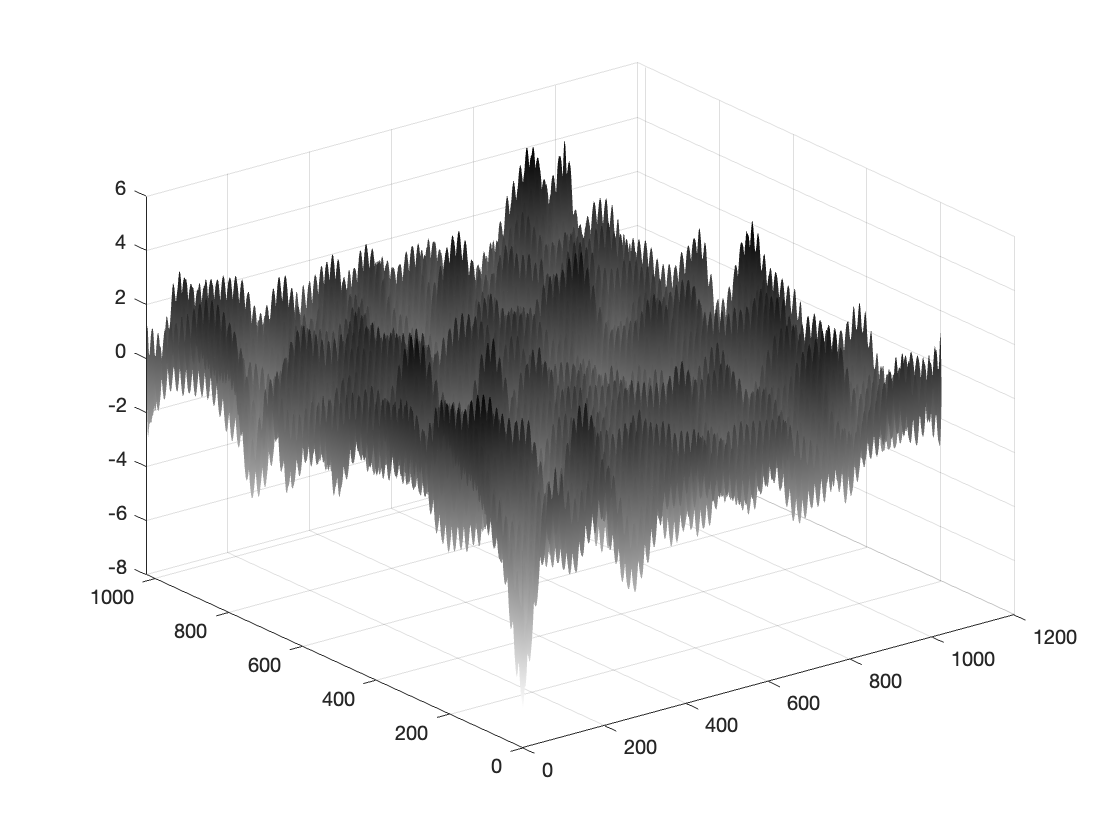


surf(lattice2);
shading interp

% axis image

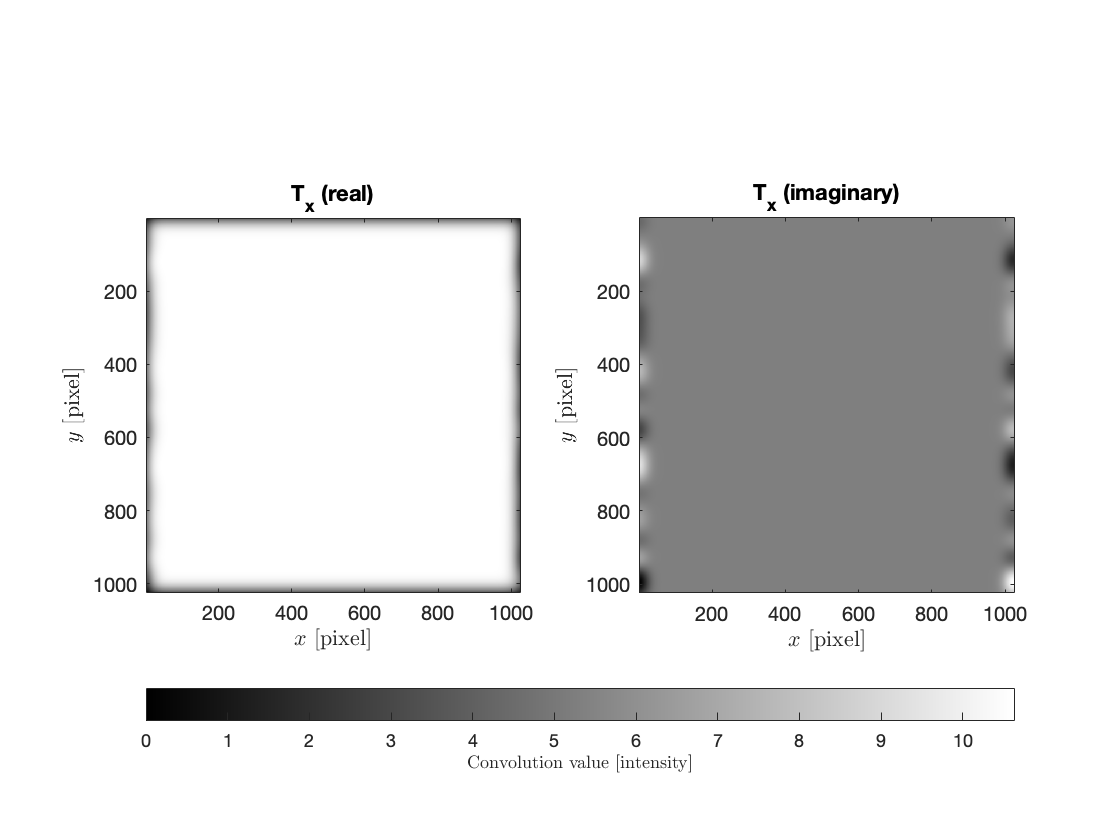

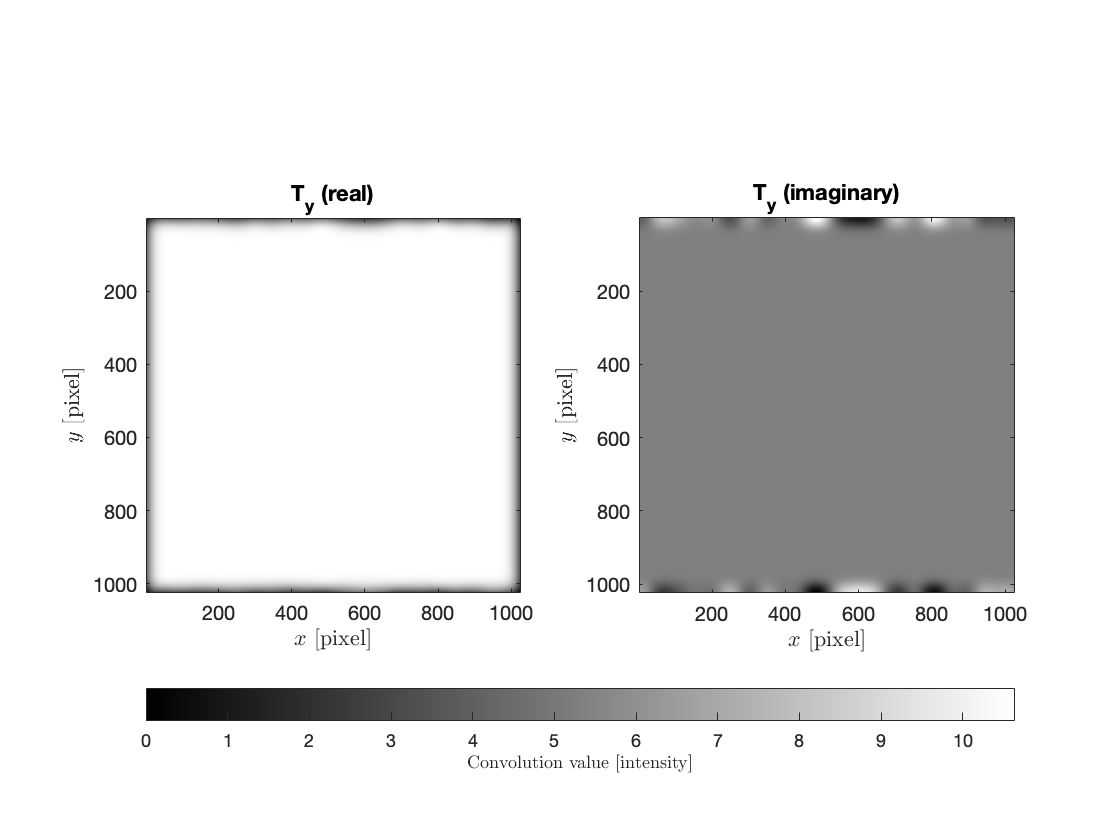

u2 = zeros(image_height,image_length,2);

tic
ucalc = myConv(lattice2,Q_x,Q_y,lambda);

toc

Elapsed time is 19.667131 seconds.


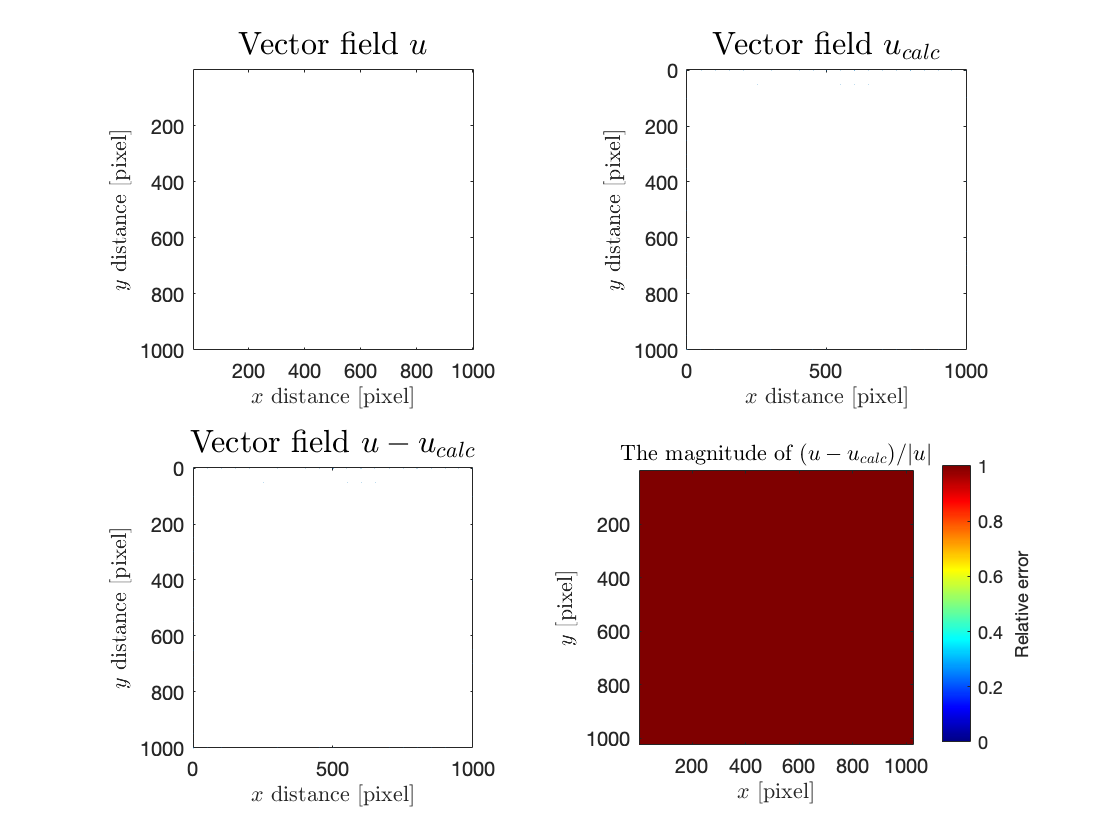


uComboPlot(u2,ucalc);

## Functions

Included here are the list of parameters for every user-defined function in this directory that might be useful in this script.

#### Local

function s = uCreate(h,l, max_disp,drift,hyst,creep)
    s = zeros(h,l,2);
    scale_coor = 1; % to scale the coordinates of the vector field
    if nargin<3
        max_disp = 1; % maximum displacement
        % to scale the magnitude of the vectors in the vector field
    end
    
    % define optional parameters
    if ~exist("drift","var")
        drift = [0 0];
    end
    if ~exist("hyst","var")
        hyst = [0 0];
    end
    if ~exist("creep","var")
        creep = [0 0];
    end
    
    % create x and y for spatial dependence
    [x,y] = meshgrid(1:l,1:h);
    x = scale_coor.*x./l;
    y = scale_coor.*y./h;
    
    %create t for temporal dependence (like raster scan)
    t = 1:h*l;
    t = reshape(t,[l h])';
%     t(2:2:end,:) = fliplr(t(2:2:end,:)); % for retrace along the next row (wrong)
    
    % thermal drift
    drift_x = t/(h*l);
    drift_y = t/(h*l);
    
    % piezoelectric hysteresis (quadratic for now, FIX LATER)
    hyst_x = -x.*(x-1);
    hyst_y = -y.*(y-1);
%     hyst_x(2:2:end) = -hyst_x(2:2:end); % for retrace along the next row
%     hyst_y(2:2:end) = -hyst_y(2:2:end); % but this is wrong
    
    % piezoelectric creep (not so well-behaved, FIX LATER)
    creep_x = log(t);
    creep_y = log(t);
    
    % change these to change the vector field u
    s(:,:,1) = drift(1)*drift_x+hyst(1)*hyst_x+creep(1)*creep_x;
    s(:,:,2) = drift(2)*drift_y+hyst(2)*hyst_y+creep(2)*creep_y;
    
    s = s/max(abs(s),[],"all")*max_disp;
    if isnan(s)
        s = zeros(h,l,2);
    end
    
%     uPlot(s,"$u$");
end

#### The big ones

Q = myFFT(P, nm, dip) —* P is the image; nm is the title; dip=[0.65 1] [optional] sets the limits of the colorbar where 1 is the value of the second highest peak; Q is the fft*

**(!) **s = uCreate(h,l, scale_mag) —* s is the vector field; h, l are the matrix dimensions; scale_mag=15 [optional] scales the magnitudes of the vectors*

P = uTransform(s,qx,qy) —* P is the image matrixl s is the vector field; qx, qy are the lattice wavevectors*

blat = myConv(lat,qx,qy,lamb) —* blat is the vector field result of the convolution; lat is the image matrix; qx, qy are the lattice wavevectors; lamb is *$\Lambda_u$ in Lawler et al. (2010)'s supplementary information paper

#### Plotting

latticePlot(P0,nm1,r,num) — *P0 is the image (uint8); nm1 is the title; r [optional], num=8 [optional] specify the view*

comboPlot(P0, nm, a) — * P0 is the image (uint8); nm1 is the title; a is the atom diameter*

uPlot(s,nm) —* s is the vector field; nm is the title*

convPlot(lat,nm) —* lat is the image lattice; nm is the title*

uComboPlot(u,ucalc) —* u is the known vector field; ucalc is the calculated vector field*

#### Miscellaneous

A = normies(A, lim) —* A is the matrix; lim=[-1 1] [optional] are the limits*